clc,clear,close all

% f: 函数
f = @(x) 1./(1+25*x.^2);

% x_train: 插值点
x_train = -1:0.2:1;     %注意，这里 x_train 应该输入一个行向量

% y_train: 插值点处的函数值
y_train = f(x_train);

% x: 要预测的点
x0= -1:0.01:1;

% y: 预测的函数值
interpolation_function = myfun(x_train,y_train);
interpolation_function = matlabFunction(interpolation_function);
y = interpolation_function(x0);

% y_real: 真实的函数值
y_real = f(x0);

% interpolation_error: 误差. F 范数
interpolation_error = norm(y_real-y);

% 输出结果
disp('插值拟合结果为')

插值拟合结果为


disp(y)

  列 1 至 15

    0.0385    0.7261    1.2303    1.5810    1.8044    1.9236    1.9590    1.9279    1.8458    1.7257    1.5787    1.4143    1.2402    1.0631    0.8881

  列 16 至 30

    0.7195    0.5604    0.4135    0.2802    0.1618    0.0588   -0.0286   -0.1007   -0.1580   -0.2013   -0.2315   -0.2496   -0.2569   -0.2546   -0.2439

  列 31 至 45

   -0.2262   -0.2026   -0.1743   -0.1426   -0.1083   -0.0726   -0.0363   -0.0003    0.0349    0.0685    0.1000    0.1291    0.1554    0.1786    0.1987

  列 46 至 60

    0.2156    0.2292    0.2397    0.2472    0.2518    0.2538    0.2534    0.2510    0.2469    0.2414    0.2350    0.2278    0.2204    0.2131    0.2062

  列 61 至 75

    0.2000    0.1949    0.1912    0.1890    0.1888    0.1906    0.1946    0.2010    0.2099    0.2213    0.2353    0.2519    0.2710    0.2926    0.3165

  列 76 至 90

    0.3426    0.3708    0.4009    0.4326    0.4657    0.5000    0.5352    0.5710    0.6070    0.6432    0.6790    0.7142    0.7486    0.7817    0.8134

  列 91 至 10

disp('真实值为')

真实值为


disp(y_real)

  列 1 至 15

    0.0385    0.0392    0.0400    0.0408    0.0416    0.0424    0.0433    0.0442    0.0451    0.0461    0.0471    0.0481    0.0491    0.0502    0.0513

  列 16 至 30

    0.0525    0.0536    0.0549    0.0561    0.0575    0.0588    0.0602    0.0617    0.0632    0.0648    0.0664    0.0681    0.0698    0.0716    0.0735

  列 31 至 45

    0.0755    0.0775    0.0796    0.0818    0.0841    0.0865    0.0890    0.0916    0.0943    0.0971    0.1000    0.1031    0.1063    0.1096    0.1131

  列 46 至 60

    0.1168    0.1206    0.1246    0.1289    0.1333    0.1379    0.1428    0.1479    0.1533    0.1590    0.1649    0.1712    0.1779    0.1848    0.1922

  列 61 至 75

    0.2000    0.2082    0.2169    0.2261    0.2358    0.2462    0.2571    0.2686    0.2809    0.2939    0.3077    0.3223    0.3378    0.3543    0.3717

  列 76 至 90

    0.3902    0.4098    0.4306    0.4525    0.4756    0.5000    0.5256    0.5525    0.5806    0.6098    0.6400    0.6711    0.7030    0.7353    0.7678

  列 91 至 10

disp('误差为')

误差为


disp(interpolation_error)

    8.2077



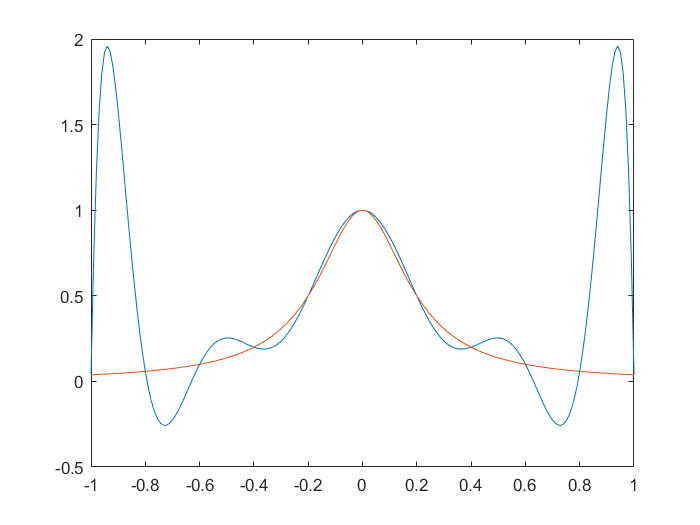

plot(x0,y)
hold on
plot(x0,y_real)